% load sensor.mat
load sensor2.mat

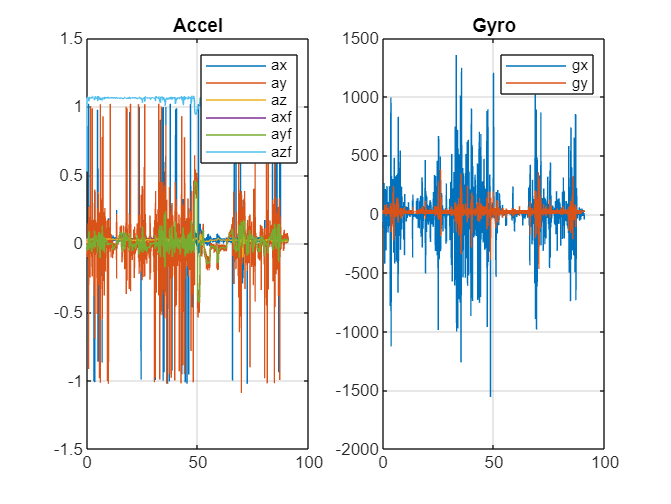

n_start = 1;
ax = find(logsout,'ax').Values.Data(n_start:end);
ay = find(logsout,'ay').Values.Data(n_start:end);
az = find(logsout,'az').Values.Data(n_start:end);

n_medfilt = 30;

axf = medfilt1(ax,n_medfilt);
ayf = medfilt1(ay,n_medfilt);
azf = medfilt1(az,n_medfilt);

gx = find(logsout,'gx').Values.Data(n_start:end);
gy = find(logsout,'gy').Values.Data(n_start:end);
% gz = find(logsout,'gz').Values.Data(n_start:end);

gxf = medfilt1(gx,n_medfilt);
gyf = medfilt1(gy,n_medfilt);
% gzf = medfilt1(gz,n_medfilt);

tiltAngleRad = find(logsout,'tiltAngleRad').Values.Data(n_start:end,:);
compFilter = find(logsout,'compFilt').Values.Data(n_start:end,:);

sampleTime = 0.01;
N = length(ax);
t = [0:N-1]*sampleTime;

figure()
subplot(1,2,1)
plot(t,ax)
hold on
plot(t,ay)
plot(t,axf)
plot(t,azf)
plot(t,ayf)
plot(t,azf)
hold off
title('Accel')
legend('ax','ay','az','axf','ayf','azf')
grid on

subplot(1,2,2)
plot(t,gx)
hold on
plot(t,gy)
hold off
title('Gyro')
legend('gx','gy')
grid on

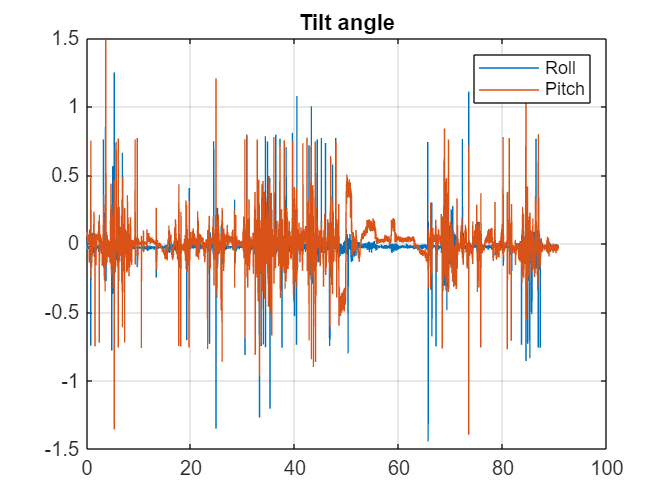


figure()
plot(t,tiltAngleRad)
title('Tilt angle')
legend('Roll','Pitch')
grid on

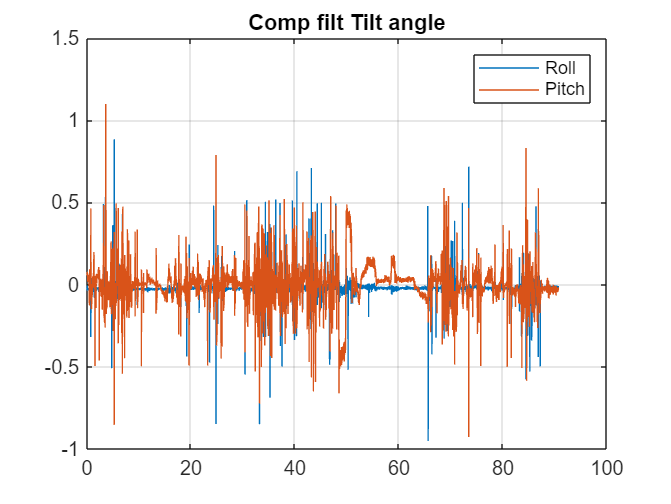


figure()
plot(t,compFilter)
title('Comp filt Tilt angle')
legend('Roll','Pitch')
grid on

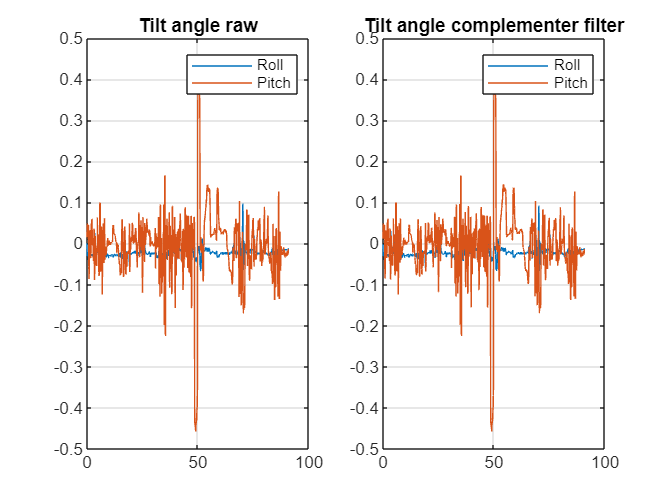


% Testing the complementary algorithm on the measurement
tiltAnglef = zeros(N,2);
measRollPitchf = zeros(N,2);
params = struct();
for i = 1:N
    [tiltAngle_temp,measRollPitch_temp] = compTiltFilter(axf(i), ayf(i), azf(i), gxf(i), gyf(i), sampleTime);
    tiltAnglef(i,:) = tiltAngle_temp;
    measRollPitchf(i,:) = measRollPitch_temp;
end

figure()
subplot(1,2,1)
plot(t,measRollPitchf)
title('Tilt angle raw')
legend('Roll','Pitch')
grid on

subplot(1,2,2)
plot(t,tiltAnglef)
title('Tilt angle complementer filter')
legend('Roll','Pitch')
grid on